# 1D advection

Setup parameters

h = 1.25;
dt = 1;
X = 300;
T = 160;
x = 0:h:X;
l = length(x);
Y = zeros(1, l);
for i = 1:length(x)
    if x(i) > 49 && x(i) < 111
        Y(i) = 100*sin(pi*(x(i)-50)/60);
    end
end
Y = repmat(Y, T+1, 1);

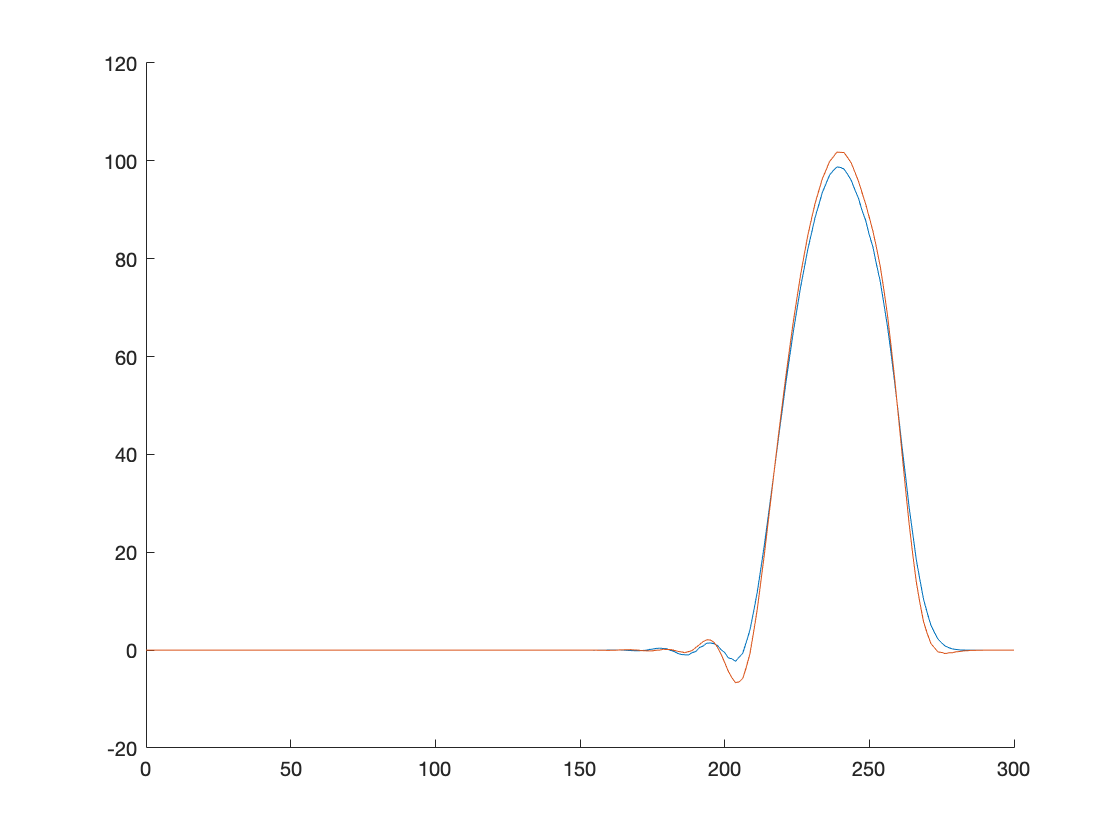

residual = 11.7838
residual = 16.5288


Z1 = multilevel_parareal(Y, h, dt, @advection_explicit, @linear_restriction, @ave_update_prolongation, 16, 2);

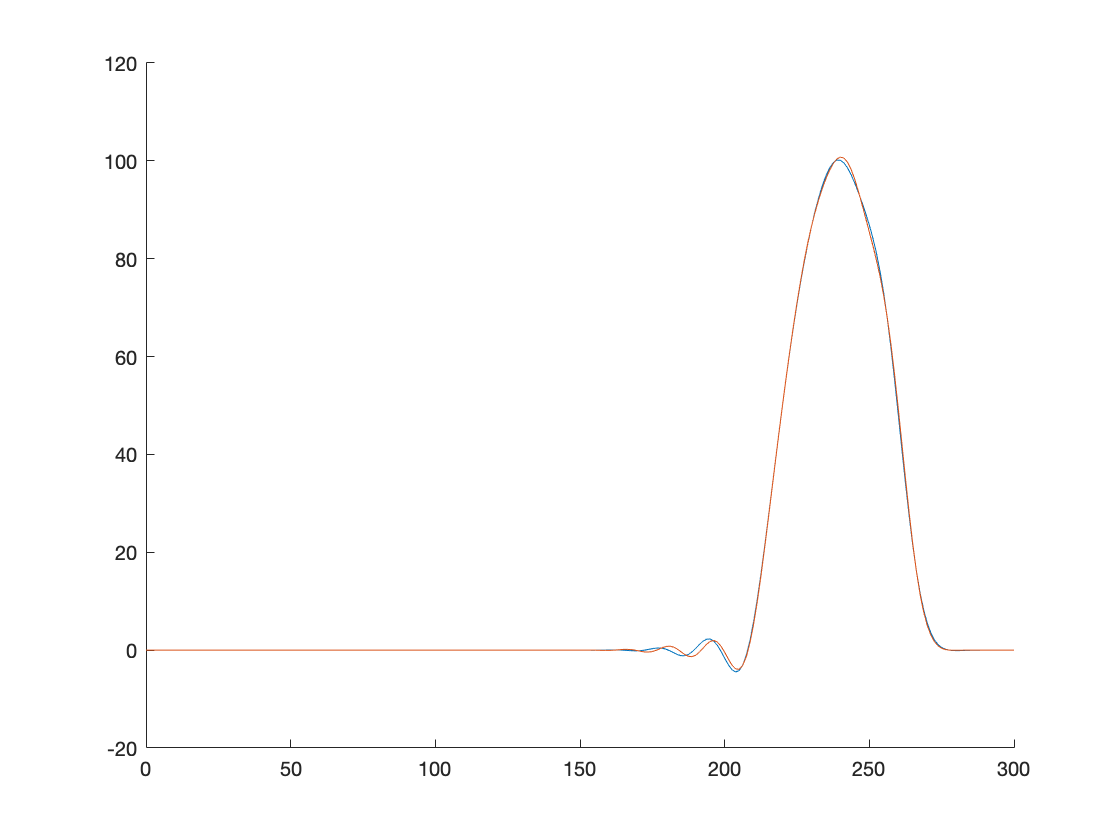

residual = 10.1981
residual = 4.0679


Z2 = multilevel_parareal(Y, h, dt, @advection_explicit, @linear_restriction, @spline_prolongation, 16, 2);

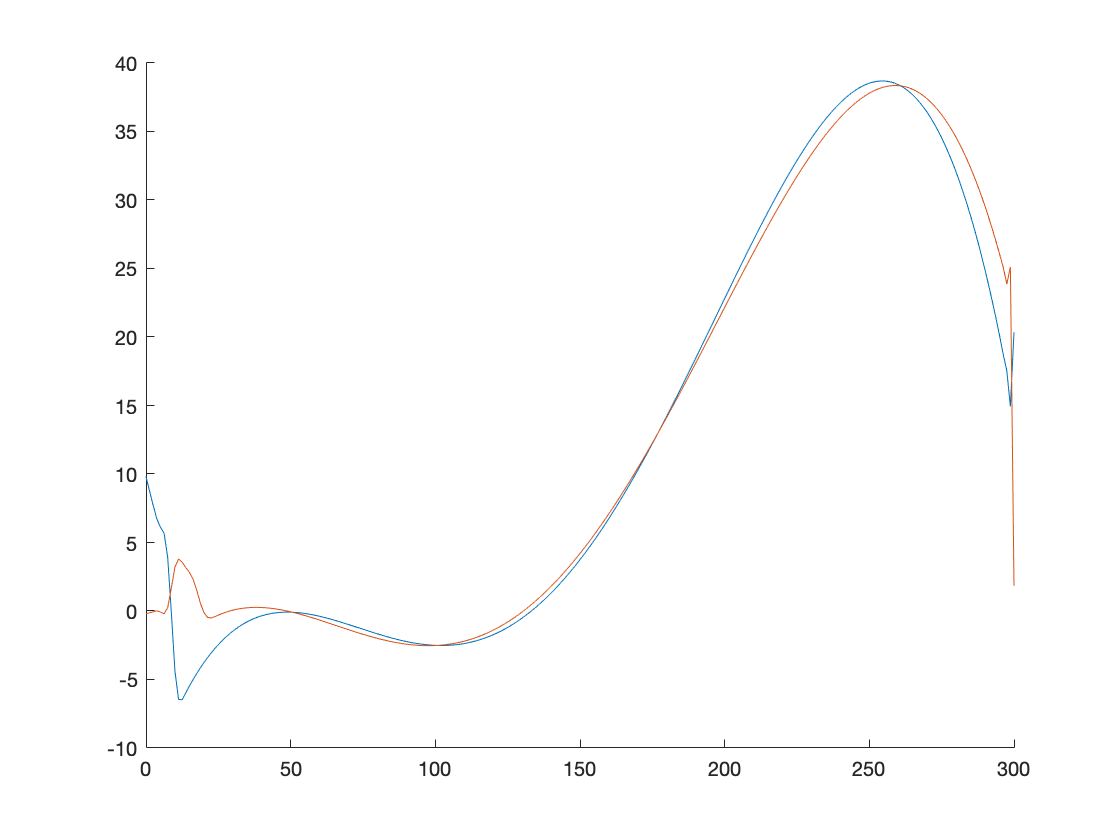

residual = 83.2516
residual = 15.7169


Z3 = multilevel_parareal(Y, h, dt, @advection_explicit, @linear_restriction, @polyval_prolongation, 16, 2);

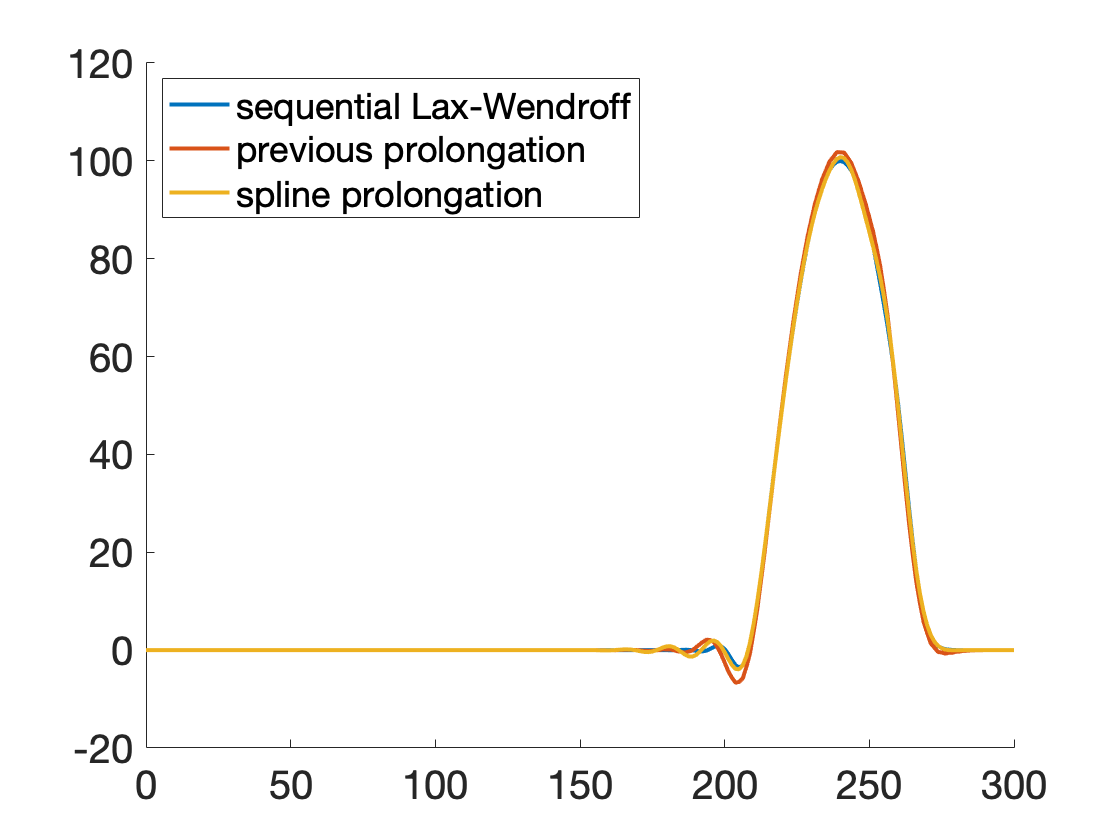

figure
set(gca, 'FontSize', 20)
hold on
Z = Y;
for i = 1:T
    Z(i + 1, :) = Lax_Wendroff(Z(i, :), h, dt);
end
plot(x, Z(end, :), "LineWidth", 2)
plot(x, Z1(end, :), "LineWidth", 2)
plot(x, Z2(end, :), "LineWidth", 2)
% plot(x, Z3(end, :), "LineWidth", 2)
legend({"sequential Lax-Wendroff", "previous prolongation", "spline prolongation"}, "Location", "northwest")